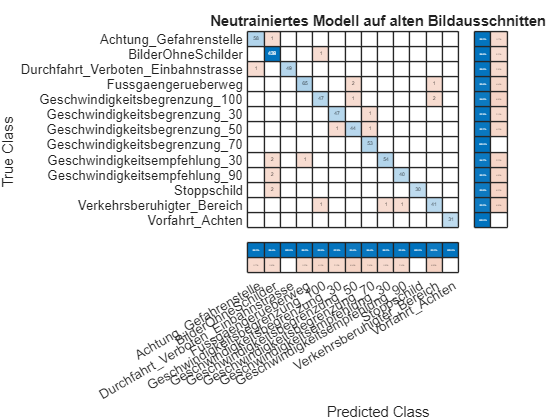

%% Einstellungen
% Vollstaendiges Auswertungsskript mit integriertem Konfidenzdiagramm.
% Keine zusaetzliche Funktionsdatei erforderlich.

imageFolder = 'C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFürTrainingNeueVorverarbeitung';
modellDatei = 'meinNetz_weitertrainiertGroßMisch.mat';
auswertungsTitel = "Neutrainiertes Modell auf alten Bildausschnitten";

excelDatei = "Klassenkennzahlen_neutrainiertes_Modell_alte_Bilder.xlsx";
konfidenzCSV = "Konfidenzanalyse_neutrainiertes_Modell_alte_Bilder.csv";
konfidenzPNG = "Konfidenzanalyse_neutrainiertes_Modell_alte_Bilder.png";

zeigeFalscheBilder = false;
maxFalscheBilder = 200;

%% Bilder laden und auf 48 x 48 Pixel skalieren
imdsSchilder = imageDatastore(imageFolder, ...
    "IncludeSubfolders", true, "LabelSource", "foldernames");

augTrain = augmentedImageDatastore([48 48 3], imdsSchilder, ...
    "ColorPreprocessing", "none", "OutputSizeMode", "resize");

modell = load(modellDatei, "net");
net = modell.net;

TTrain = imdsSchilder.Labels(:);
% Wie bisher: Diese Reihenfolge entspricht deiner bestaetigten
% Klassenreihenfolge beim Training und damit den Modellausgaengen.
classNames = categories(TTrain);
klassen = string(classNames(:));
anzahlBilder = numel(TTrain);
anzahlKlassen = numel(classNames);
assert(anzahlBilder > 0, "Der Bildordner enthaelt keine Bilder.");

tbl = readall(augTrain);
imgs = tbl{:, 1};
XTrain = single(cat(4, imgs{:}));
% Nur in single umwandeln: KEINE Division durch 255 und kein im2single.

%% Vorhersagen berechnen
outputs = minibatchpredict(net, XTrain);

% Ausgabe fuer alle folgenden Auswertungen einheitlich ausrichten:
% Zeilen = Bilder, Spalten = Klassen.
if isa(outputs, "dlarray")
    scores = extractdata(outputs);
else
    scores = outputs;
end
if isa(scores, "gpuArray")
    scores = gather(scores);
end
scores = squeeze(double(scores));

if anzahlBilder == anzahlKlassen
    error("Gleich viele Bilder und Klassen: Score-Ausrichtung ist mehrdeutig. " + ...
        "Bitte einen Datensatz mit anderer Bildanzahl auswerten.");
elseif isequal(size(scores), [anzahlBilder anzahlKlassen])
    % Bereits in der richtigen Anordnung.
elseif isequal(size(scores), [anzahlKlassen anzahlBilder])
    scores = scores.';
else
    error("Score-Groesse %s passt nicht zu %d Bildern und %d Klassen.", ...
        mat2str(size(scores)), anzahlBilder, anzahlKlassen);
end

assert(all(isfinite(scores(:))) && ...
    all(scores(:) >= -1e-6 & scores(:) <= 1 + 1e-6) && ...
    all(abs(sum(scores, 2) - 1) < 1e-3), ...
    "Die Modellausgabe muss Softmax-Scores zwischen 0 und 1 enthalten.");

[konfidenz, vorherIndex] = max(scores, [], 2);
YTrain = categorical(classNames(vorherIndex), classNames, classNames);
YTrain = YTrain(:);

%% Confusion Matrix mit Precision und Recall
classOrder = categorical(classNames, classNames, classNames);
confMat = confusionmat(TTrain, YTrain, "Order", classOrder);

figure("Color", "w");
cm = confusionchart(confMat, classNames);
cm.Title = auswertungsTitel;
cm.Normalization = "absolute";
cm.RowSummary = "row-normalized";       % Recall rechts
cm.ColumnSummary = "column-normalized"; % Precision unten


%% Precision, Recall und F1 je Klasse
truePositive = diag(confMat);
anzahlTatsaechlich = sum(confMat, 2);
anzahlVorhergesagt = sum(confMat, 1).';

recall = truePositive ./ anzahlTatsaechlich;
precision = truePositive ./ anzahlVorhergesagt;
recall(~isfinite(recall)) = 0;
precision(~isfinite(precision)) = 0;

f1Score = 2 .* precision .* recall ./ (precision + recall);
f1Score(~isfinite(f1Score)) = 0;

kennzahlen = table( ...
    klassen, anzahlTatsaechlich, anzahlVorhergesagt, truePositive, ...
    precision * 100, recall * 100, f1Score * 100, ...
    'VariableNames', ["Klasse", "TatsaechlicheBilder", ...
    "VorhergesagteBilder", "RichtigErkannt", "PrecisionProzent", ...
    "RecallProzent", "F1Prozent"]);

disp(kennzahlen);

                   Klasse                   TatsaechlicheBilder    VorhergesagteBilder    RichtigErkannt    PrecisionProzent    RecallProzent    F1Prozent
    ____________________________________    ___________________    ___________________    ______________    ________________    _____________    _________

    "Achtung_Gefahrenstelle"                         59                     59                  58               98.305            98.305         98.305  
    "BilderOhneSchilder"                            440                    446                 439                98.43            99.773         99.097  
    "Durchfahrt_Verboten_Einbahnstrasse"             50                     49                  49                  100                98    

writetable(kennzahlen, excelDatei);
fprintf("Kennzahlen gespeichert unter:\n%s\n", fullfile(pwd, excelDatei));

Kennzahlen gespeichert unter:
C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\04_ModelleTrainieren\Klassenkennzahlen_neutrainiertes_Modell_alte_Bilder.xlsx



accuracy = sum(truePositive) / sum(confMat(:));
fprintf("Accuracy: %.2f %%\n", accuracy * 100);

Accuracy: 97.84 %



%% Konfidenzen und wahre Klassen fuer jedes einzelne Bild
hintergrundIndex = find(klassen == "BilderOhneSchilder", 1);
assert(~isempty(hintergrundIndex), ...
    "Die Klasse BilderOhneSchilder fehlt. Bitte den Klassennamen pruefen.");

[bekannt, wahrIndex] = ismember(string(TTrain), klassen);
assert(all(bekannt), "Ein wahres Label fehlt in classNames.");
istHintergrund = wahrIndex == hintergrundIndex;
richtig = vorherIndex == wahrIndex;

[sortierteScores, sortierteIndizes] = sort(scores, 2, "descend");
zweitbesterScore = sortierteScores(:, 2);
zweitbesteKlasse = klassen(sortierteIndizes(:, 2));

analyse = table( ...
    string(imdsSchilder.Files(:)), ...
    string(TTrain), string(YTrain), ...
    100 * konfidenz, zweitbesteKlasse, 100 * zweitbesterScore, ...
    100 * (konfidenz - zweitbesterScore), ...
    100 * scores(:, hintergrundIndex), richtig, istHintergrund, ...
    'VariableNames', ["Datei", "TatsaechlicheKlasse", ...
    "VorhergesagteKlasse", "KonfidenzProzent", "ZweitbesteKlasse", ...
    "ZweitbesterScoreProzent", "AbstandProzentpunkte", ...
    "ScoreOhneSchildProzent", "Richtig", "IstHintergrund"]);

writetable(analyse, konfidenzCSV, "Delimiter", ";", "Encoding", "UTF-8");
fprintf("Konfidenz-Einzelwerte gespeichert unter:\n%s\n", ...
    fullfile(pwd, konfidenzCSV));

Konfidenz-Einzelwerte gespeichert unter:
C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\04_ModelleTrainieren\Konfidenzanalyse_neutrainiertes_Modell_alte_Bilder.csv


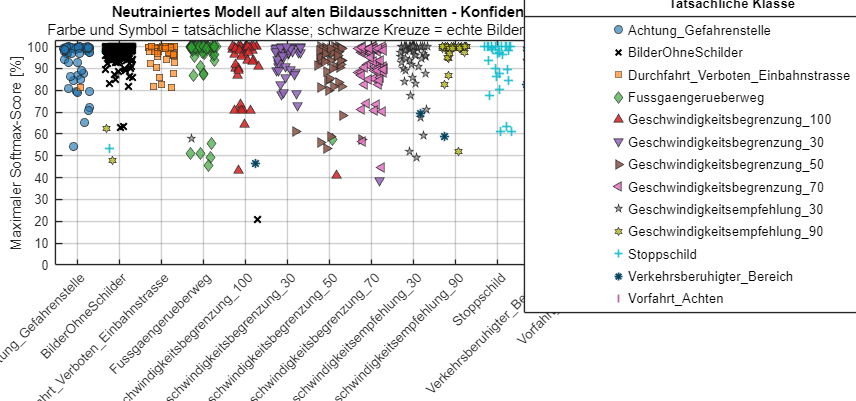


%% Konfidenzdiagramm: vorhergesagte Klasse / Score / tatsächliche Klasse
% Jeder Punkt steht für ein Bild.
% X-Achse: vorhergesagte Klasse.
% Y-Achse: höchster Softmax-Score.
% Farbe UND Symbol: tatsächliche Klasse.
% Schwarze Kreuze: tatsächliche Klasse BilderOhneSchilder.

% Reproduzierbarer horizontaler Versatz gegen Überlagerungen
plotZufall = RandStream("mt19937ar", "Seed", 42);

x = double(vorherIndex) + ...
    0.65 * (rand(plotZufall, anzahlBilder, 1) - 0.5);

y = 100 * konfidenz;

%% Deutlich unterscheidbare Farbpalette
% Die Farben werden ausschließlich den Schildklassen zugeordnet.
kontrastPalette = [
     31 119 180    % Blau
    255 127  14    % Orange
     44 160  44    % Grün
    214  39  40    % Rot
    148 103 189    % Violett
    140  86  75    % Braun
    227 119 194    % Rosa
    127 127 127    % Grau
    188 189  34    % Olivgrün
     23 190 207    % Türkis
      0  63  92    % Dunkelblau
    188  80 144    % Magenta
] / 255;

schildIndizes = setdiff( ...
    1:anzahlKlassen, hintergrundIndex, "stable");

assert(numel(schildIndizes) <= size(kontrastPalette, 1), ...
    "Die Farbpalette enthält nicht genügend Farben.");

farben = zeros(anzahlKlassen, 3);
farben(schildIndizes, :) = ...
    kontrastPalette(1:numel(schildIndizes), :);

% BilderOhneSchilder wird schwarz dargestellt
farben(hintergrundIndex, :) = [0 0 0];

%% Unterschiedliche Symbole festlegen
markerListe = [
    "o"   % Kreis
    "s"   % Quadrat
    "d"   % Raute
    "^"   % Dreieck nach oben
    "v"   % Dreieck nach unten
    ">"   % Dreieck nach rechts
    "<"   % Dreieck nach links
    "p"   % Fünfeck
    "h"   % Sechseck
    "+"   % Plus
    "*"   % Stern
    "|"   % Senkrechter Strich
];

markerProKlasse = strings(anzahlKlassen, 1);
markerProKlasse(schildIndizes) = ...
    markerListe(1:numel(schildIndizes));

% Hintergrundklasse immer als schwarzes Kreuz
markerProKlasse(hintergrundIndex) = "x";

% Diese Marker können gefüllt dargestellt werden
gefuellteMarker = [
    "o", "s", "d", "^", "v", ">", "<", "p", "h"
];

%% Diagramm erzeugen
figKonfidenz = figure( ...
    "Color", "w", ...
    "Name", "Konfidenzanalyse", ...
    "Position", [50 50 1800 940]);

ax = axes("Parent", figKonfidenz);
hold(ax, "on");

plotHandles = gobjects(anzahlKlassen, 1);

% Hintergrundbilder zuletzt zeichnen, damit die Kreuze sichtbar bleiben
zeichenReihenfolge = [
    schildIndizes, hintergrundIndex
];

for k = zeichenReihenfolge

    idx = wahrIndex == k;

    xk = x(idx);
    yk = y(idx);

    % Leeren Legendeneintrag trotzdem erzeugen
    if isempty(xk)
        xk = NaN;
        yk = NaN;
    end

    aktuellerMarker = markerProKlasse(k);

    if k == hintergrundIndex

        % Hintergrundbilder deutlich als schwarze Kreuze
        plotHandles(k) = scatter( ...
            ax, xk, yk, 48, ...
            "Marker", "x", ...
            "MarkerEdgeColor", "k", ...
            "LineWidth", 1.5);

    elseif any(aktuellerMarker == gefuellteMarker)

        % Gefüllte Symbole mit dunkler Umrandung
        plotHandles(k) = scatter( ...
            ax, xk, yk, 38, ...
            "Marker", char(aktuellerMarker), ...
            "MarkerFaceColor", farben(k, :), ...
            "MarkerEdgeColor", [0.15 0.15 0.15], ...
            "MarkerFaceAlpha", 0.65, ...
            "MarkerEdgeAlpha", 0.85, ...
            "LineWidth", 0.6);

    else

        % Linienmarker wie Plus, Stern und senkrechter Strich
        plotHandles(k) = scatter( ...
            ax, xk, yk, 48, ...
            "Marker", char(aktuellerMarker), ...
            "MarkerEdgeColor", farben(k, :), ...
            "MarkerEdgeAlpha", 0.9, ...
            "LineWidth", 1.4);

    end
end

%% Achsen formatieren
xlim(ax, [0.5 anzahlKlassen + 0.5]);
ylim(ax, [0 103]);

xticks(ax, 1:anzahlKlassen);
xticklabels(ax, klassen);
xtickangle(ax, 45);

yticks(ax, 0:10:100);

ax.TickLabelInterpreter = "none";
ax.FontSize = 10;
ax.GridAlpha = 0.22;
ax.MinorGridAlpha = 0.12;

grid(ax, "on");
box(ax, "on");

xlabel(ax, "Vorhergesagte Klasse");
ylabel(ax, "Maximaler Softmax-Score [%]");

title( ...
    ax, ...
    auswertungsTitel + " - Konfidenzen", ...
    "Interpreter", "none");

subtitle( ...
    ax, ...
    "Farbe und Symbol = tatsächliche Klasse; " + ...
    "schwarze Kreuze = echte BilderOhneSchilder");

%% Legende
lgd = legend( ...
    ax, ...
    plotHandles, ...
    classNames, ...
    "Location", "eastoutside", ...
    "Interpreter", "none", ...
    "FontSize", 10);

lgd.Title.String = "Tatsächliche Klasse";
lgd.AutoUpdate = "off";

% Platz für Klassennamen und Legende
ax.Units = "normalized";
ax.Position = [0.065 0.34 0.64 0.56];

lgd.Units = "normalized";
lgd.Position = [0.72 0.40 0.27 0.45];

hold(ax, "off");

%% Diagramm speichern
drawnow;

exportgraphics( ...
    figKonfidenz, ...
    konfidenzPNG, ...
    "Resolution", 200, ...
    "BackgroundColor", "white");


fprintf( ...
    "Konfidenzdiagramm gespeichert unter:\n%s\n", ...
    fullfile(pwd, konfidenzPNG));

Konfidenzdiagramm gespeichert unter:
C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\04_ModelleTrainieren\Konfidenzanalyse_neutrainiertes_Modell_alte_Bilder.png



%% Optional: falsch erkannte Bilder anzeigen
trueLabelsTrain = TTrain;
wrongIdxtrain = find(YTrain ~= trueLabelsTrain);

if zeigeFalscheBilder
    for i = 1:min(maxFalscheBilder, numel(wrongIdxtrain))
        idx = wrongIdxtrain(i);
        img = readimage(imdsSchilder, idx);
        figure;
        imshow(img);
        title(sprintf("Vorhersage: %s (%.1f %%) | Richtig: %s", ...
            char(string(YTrain(idx))), 100 * konfidenz(idx), ...
            char(string(trueLabelsTrain(idx)))), "Interpreter", "none");
    end
end
